% 定义变量范围
D = linspace(0.01, 0.5, 100);  % D 的范围从 0 到 0.5
phi = linspace(0, 0.99, 100);  % phi 的范围从 0 到 1

% 创建网格
[D_grid, phi_grid] = meshgrid(D, phi);

% 预分配 M 的矩阵
inv_M = zeros(size(D_grid));

% 计算不同情况下 M 的值
for i = 1:length(phi)
    for j = 1:length(D)
        % 获取当前的 D 和 phi
        D_val = D(j);
        phi_val = phi(i);
        
        % 根据不同的条件计算 M
        if (0 <= phi_val) && (phi_val < 0.5)
            inv_M(i,j) = (1-4*phi_val)/(2*D_val);                  
        elseif (0.5 <= phi_val) && (phi_val < 1)
            inv_M(i,j) = (4*phi_val -3)/(2*D_val);
        end
    end
end

% % 限制 M 的范围在 0 到 2 之间
 inv_M(inv_M < 0) = 0;
 inv_M(inv_M > 3) = 3;

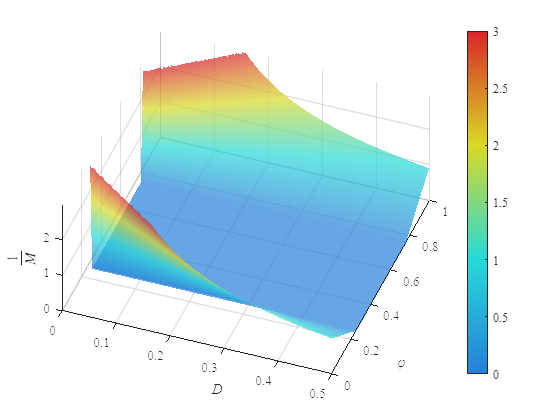

% 绘制3D图
figure;
surf(D_grid, phi_grid, inv_M,'FaceAlpha', 0.7);

% 禁用边框线
set(gca, 'FontName', 'Times New Roman');
%set(gca, 'EdgeColor', 'none'); % 这行可以去掉曲面连接线

% 设置颜色映射
n = 256; % 定义颜色分辨率
cmap = [linspace(0, 0, n/4)', linspace(0.5, 1, n/4)', linspace(1, 1, n/4)'; ... % 蓝到绿
        linspace(0, 1, n/4)', linspace(1, 1, n/4)', linspace(1, 0, n/4)'; ... % 绿到黄
        linspace(1, 1, n/4)', linspace(1, 0, n/4)', linspace(0, 0, n/4)'];    % 黄到红
gray_level = 0.5; % 接近灰色的值（0.5是中性灰）
desaturated_cmap = cmap * 0.7 + gray_level * (1 - 0.7); % 线性插值降低饱和度
colormap(desaturated_cmap);
colorbar;

% 平滑显示
shading interp;  % 平滑插值

% 设置视角和网格
view(20,60); % 设置视角
grid on;
hold on;
% 添加标题和标签
xlabel('\it{D}');
ylabel('\it{φ}');
zlabel('$\frac{1}{M}$', 'Interpreter', 'latex');
zlim([0,2.99])

% 绘制 M = 1 的平面
% 找到 M = 1 的位置
hold on;

%contour3(D_grid, phi_grid, inv_M, [1, 1], 'LineWidth', 2, 'LineColor', 'k');


%text(0.1, 0.4, 2, 'ZVS Region', 'FontSize', 12, 'Color', 'black', 'HorizontalAlignment', 'center');
%text(0.05, 0.1, 0, sprintf('Non-ZVS\nRegion'), 'FontSize', 12, 'Color', 'black', 'HorizontalAlignment', 'center');

%text(0.1, 0.1, 0, 'Non-ZVS \n Region', 'FontSize', 12, 'Color', 'black', 'HorizontalAlignment', 'center');


% 箭头指离'Non-ZVS Region'文本
%annotation('arrow', [0.17, 0.17], [0.33, 0.23], 'Color', 'black', 'LineWidth', 2);
% 箭头指向'ZVS Region'文本
%annotation('arrow', [0.3, 0.3], [0.63, 0.73], 'Color', 'black', 'LineWidth', 2);

% 绘制文本时更改为 Times New Roman 字体
%text(0.1, 0.4, 2, 'ZVS Region', 'FontSize', 12, 'FontName', 'Times New Roman', 'FontWeight', 'bold', 'Color', 'black', 'HorizontalAlignment', 'center');
%text(0.05, 0.4, 0.5, 'Non-ZVS\nRegion', 'FontSize', 12, 'FontName', 'Times New Roman', 'FontWeight', 'bold', 'Color', 'black', 'HorizontalAlignment', 'center');

% 只绘制箭头，删除文本
%annotation('arrow', [0.26, 0.26], [0.37, 0.27],  'String', 'Non-ZVS Region', 'FontSize', 12, 'FontName', 'Times New Roman', 'FontWeight', 'bold','Color', 'black','LineWidth', 2, 'HeadWidth', 15, 'HeadLength', 10, 'Color', 'black');
%annotation('arrow', [0.28, 0.28], [0.6, 0.7], 'LineWidth', 2, 'HeadWidth', 15, 'HeadLength', 10, 'Color', 'black');

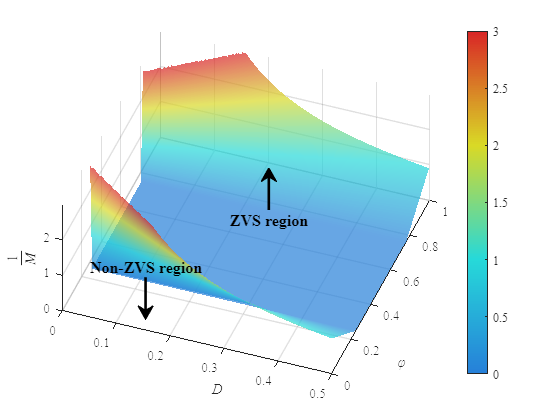

% 绘制 ZVS Region 文本，单独显示，设置为 Times New Roman 字体和加粗
%text(0.1, 0.4, 2, 'ZVS Region', 'FontSize', 12, 'FontName', 'Times New Roman', 'FontWeight', 'bold', 'Color', 'black', 'HorizontalAlignment', 'center');

% 只绘制箭头，并使 Non-ZVS Region 文本跟随箭头
% 箭头的起点是 (0.26, 0.37) -> (0.26, 0.27)，文本在箭头下方
annotation('textarrow', [0.26, 0.26], [0.34, 0.24], 'String', 'Non-ZVS region', 'FontSize', 12, 'FontName', 'Times New Roman', ...
    'FontWeight', 'bold', 'Color', 'black', 'LineWidth', 2, 'HeadWidth', 15, 'HeadLength', 10);

% 箭头的起点是 (0.28, 0.6) -> (0.28, 0.7)，文本在箭头上方

annotation('textarrow', [0.48, 0.48], [0.5, 0.6], 'String', 'ZVS region', 'FontSize', 12, 'FontName', 'Times New Roman', ...
    'FontWeight', 'bold', 'Color', 'black', 'LineWidth', 2, 'HeadWidth', 15, 'HeadLength', 10);

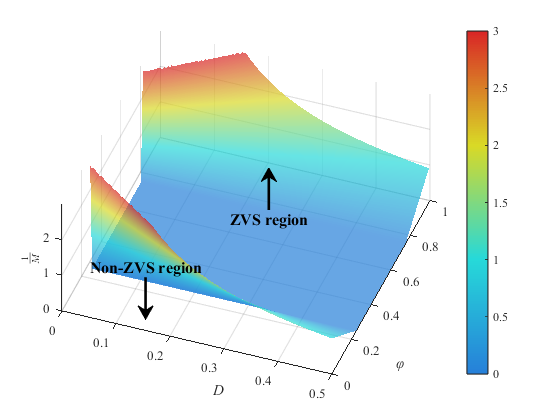

% 导出为 PDF 格式，设置输出尺寸
exportgraphics(gcf, 'ZVSLowVoltageSideS2S43DMode3.pdf', 'ContentType', 'image', 'BackgroundColor', 'none');